l = 2;
N=1000;
w = [1,1]';
w0 = 0;
a = 10;
e = 1;
sed = 0;
X = generate_hyper(w,w0,a,e,N,sed)

X =    -1.4588    9.1074    4.4849    1.6178    0.8052    4.1088   -9.8994    5.6503    8.5372   -9.8341    6.4926    5.3467    9.9427   -5.4469    8.3908    2.8400   -7.8936   -4.6368    5.2769    6.1102   -7.9149   -0.6048   -5.6188    8.4542   -3.5935    7.1509   -4.8031    7.5613   -6.2346    5.1839   -9.3662    2.8468    1.3374   -2.4718   -5.7490    5.8431   -7.0911   -0.2172   -9.7431   -6.2678   -0.2954    6.7645   -7.1789    4.6443    3.8213   -9.3101   -0.2229    9.4278   -7.7510    4.8643
    0.7965   -8.6171   -4.5307   -1.3109    0.1280   -4.4828    9.0523   -5.0675   -8.8064   10.0043   -7.1259   -6.1929  -10.6354    6.1007   -8.7889   -3.0722    8.1951    5.2715   -4.7443   -6.3619    7.2947    0.8978    4.6260   -8.8884    3.8707   -6.9667    4.4536   -6.5834    5.4811   -4.7121    8.6794   -2.9775   -0.6729    2.1916    4.9015   -5.7293    6.6390   -0.5187   10.1424    6.2396   -0.3392   -7.5621    6.5820   -5.3748   -4.1738   10.2112    0.2871   -9.9324    7.6255   -4

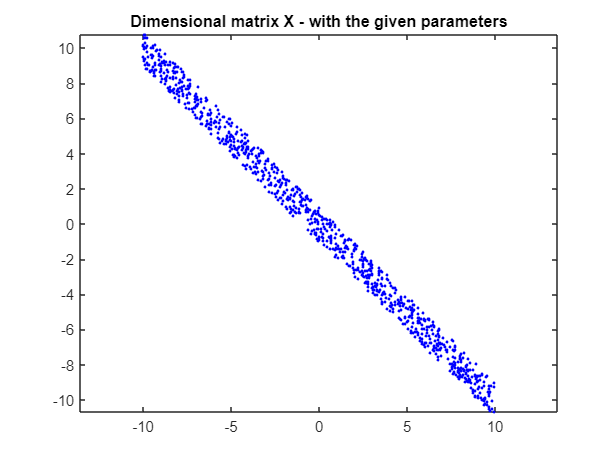

title("Dimensional matrix X - with the given parameters")

[pc,variances]=pcacov(cov(X'))

pc =    -0.7058    0.7084
    0.7084    0.7058


variances =    68.6763
    0.1591


function X=generate_hyper(w,w0,a,e,N,sed)
    l=length(w);
    t=(rand(l-1,N)-.5)*2*a;
    t_last=-(w(1:l-1)/w(l))'*t + 2*e*(rand(1,N)-.5)-(w0/w(l));
    X=[t; t_last];
%Plots for the 2d and 3d case
    if(l==2)
        figure(1), plot(X(1,:),X(2,:),'.b')
    elseif(l==3)
        figure(1), plot3(X(1,:),X(2,:),X(3,:),'.b')
    end
    figure(1), axis equal
end

